Numerische Analyse 

load Data0701.mat

Daten wurden mit Schnackerstellung1 erstellt.

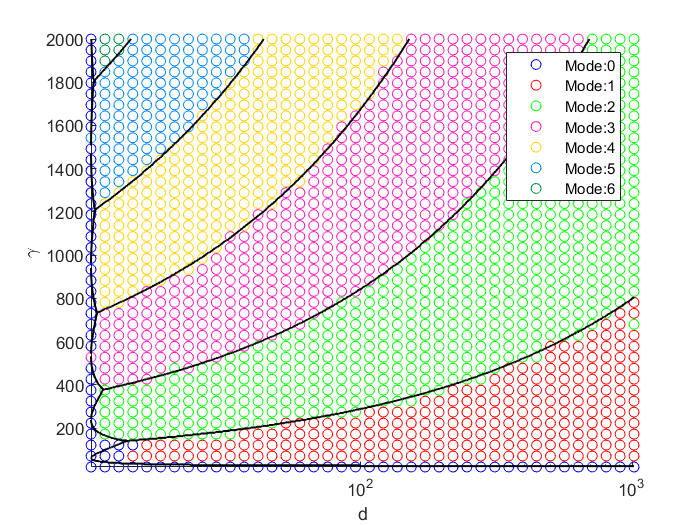

j_prom = logspace(-4,0,3);
Schnack1_linroom = Turing_room_max_mode(Schnack1_linroom,j_prom);
loglog_mode(Schnack1_linroom,"show_raster",2)

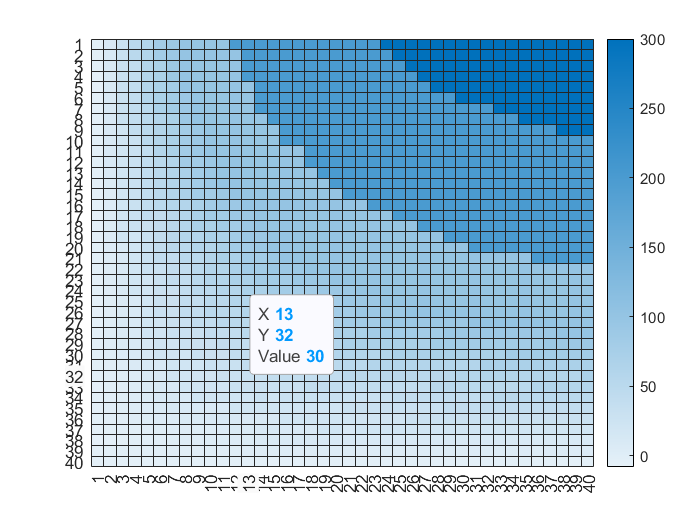

heatmap(flip(Schnack1_linroom.roundProm))

Im Bild X01 zeigt, das die Linearesierung den Erwartungen entspricht. Die wenige falschen Punkte sind Mischmuster die nahe der Grenzen entstehen. Außerhalb der Mischmuster setzen sich die jeweilige Muster, aber durch und es entstehen nur die Standardmuster im Bild X00 zusehen sind.Die Skalierung dieser Muster wächst expotential.

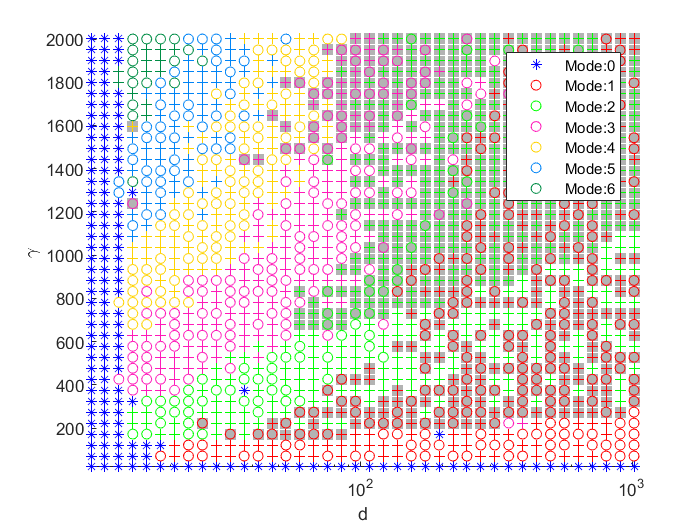

Schnack1_room = Turing_room_max_mode(Schnack1_room,j_prom);
loglog_mode2(Schnack1_room,"show_raster",0,"showSchnack",true)

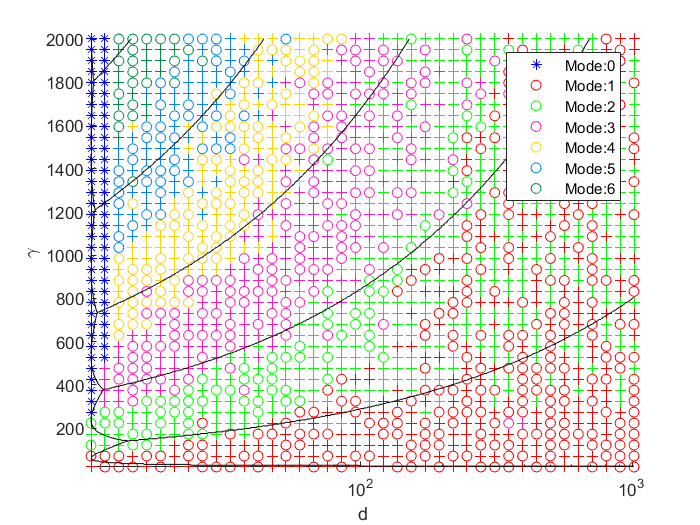

j_prom = logspace(-10,-0.3,10);
Schnack1_room = Turing_room_max_mode(Schnack1_room,j_prom);
loglog_mode2(Schnack1_room,"show_raster",2)

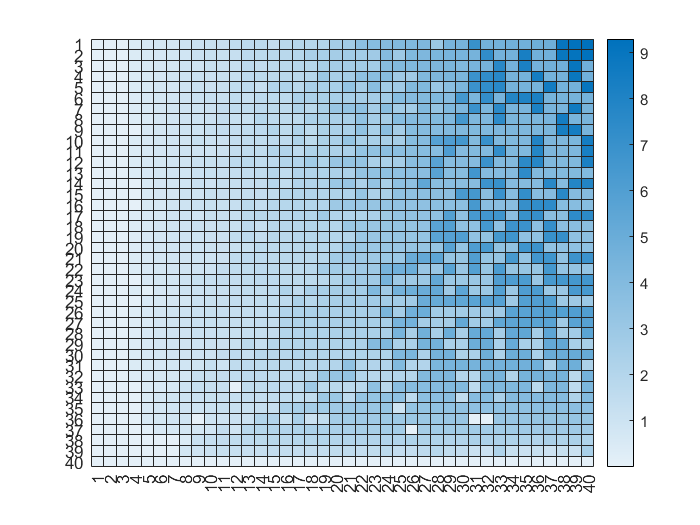

Schnack1_room.roundProm(Schnack1_room.roundProm < -1) = -1;
heatmap(flip(Schnack1_room.roundProm))

Die Muster des Schnackenbergmodells (s.Bild X03) ist nahe der Erwartungswerte. Anfangs entstehen auch Muster die in der Theorie nicht  enstehen können, da der Modus gar nicht dort linearesiert instabil ist. Diese enstehen mit sehr kleinen Amplituden nahe an d_c. Besonders bei großen \gammas ist die Amplitude der Muster so klein, dass bei der Muster Enstehung die Rolle der Maschinenungenauigkeit nicht zu vernachlässigen sind. 

Bei den kleinen Muster entstehen die Standardmuster, siehe Bild X01. Wenn man aber  \gamma und d vergrößert, sieht man die Minimas, ab einen bestimmten Punkt nicht mehr kleiner werden, während die Maximas gegen unendlich gehen. Das lässt sich erklären, wenn man die Nullklienten von Schnackenberg anschaut. Denn durch die Diffusion wird der Gleichgewichtspunkt instabil, aber die Lösungen können die Nullklienten fast nicht überqueren, dar er fast parallel zur X-Achse verläuft. Dadurch entstehen kleinere Maximas größere Moden, wobei ein Verlauf zwischen dem Standardmuster und dem Schnackenbergmuster zusehen ist, wobei in den analysierten Bereich nur die Modis 1-3 Schnackenbergmuster entstehen lassen, wobei der 4 Modus am Ende dahin entwickelt. 

Was auch aufällig ist, dass im Bereich 2b der Modus 1- beinahe verschwindet. Das lässt sich ebenfalls mit dem Nullklienten erklären, der nur einseitig die Lösungen durchlässt und ihn dann nicht mehr überqueren kann.

Solche Effekte wie sie oben beschrieben sind, werden in der Linearesierung aufgrund fehlender Nullklienten nicht sichtbar. Ein weiterer großer Unterschied ist die Linearisierung gleichmäßig exponentiel mit /gamma und d wächst. Das Schnackenberg Modell wächst aufgrund seiner nicht linearen Teile deutlich langsamer und nicht gleichmäßig.Auffällig dabei ist, das das lineare Muster im Bereich 2b deutlich stärke Amplitude hat, als das quadratische Muster. Desweiteren sind im Bereich 1a ein paar kleinere nicht lineare Muster entstanden.

Die im letzten Absatz angesprochen kleine Muster treten beim Verkleinern der Anfangsstörrungen(Von 1e-0 auf 1e-2) verhäuft auf, wie auf der Abbildung XX zusehen ist, wobei es immernoch dieselben Hauptbereiche gibt, aber die größere Moden auch in anderen Bereiche auftreten.Diese Phänomen tritt bei jeweils dem größt möglichsten Instabilenmodus auf. Verkleinern wir die Anfangstörrung auf 1e4, dann dominieren die großen Modi  die Bereiche zwei und eins b durch.

Betrachten wir dasselbe Schnackenbergmodell mit kleineren Anfangsstörungen sehen wir, dass man das Bild in die gleichen Hauptbereich unterteilen kann, aber es entstehen kleine Muster in Bereiche, wo sie der größte instabile Modus sind.

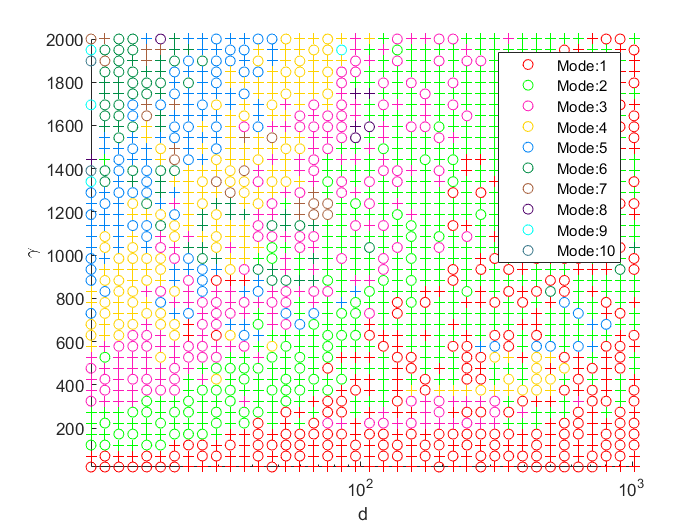

Schnack2_room = Turing_room_max_mode(Schnack2_room,j_prom);
loglog_mode2(Schnack2_room,"show_raster",0)

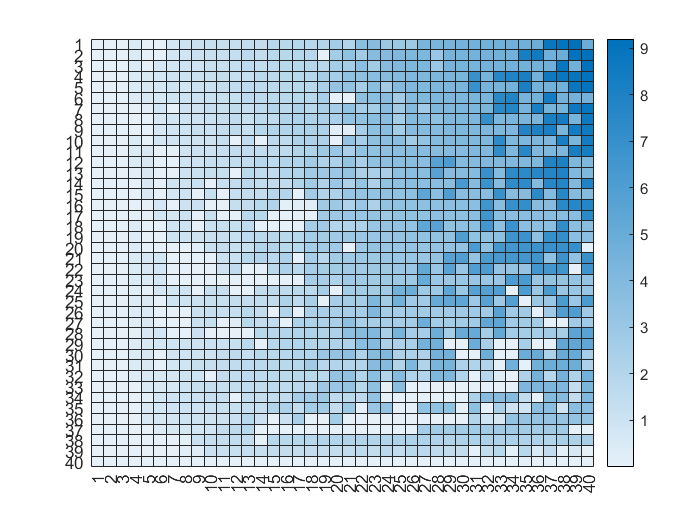


heatmap(flip(Schnack2_room.roundProm))

Verkleinern wir die Anfangstörungen weiter enstehen immer mehr dieser kleineren Mustern. Die Simulation ist wie oben beschrieben nicht robust und nehmen  wir nun den maximalen enstanden Modi heraus. Erkennen wir Bereiche, in denen kein größerer Moden entsteht. Die am obersten Bereich, den sie im ersten Schnackenbergmodell entstanden sind und mit größeren d setzt sich auch wieder der zweite Modus durch. Schauen wir uns den Median des Muster an. Erkennen wir, das im Median auch diese Muster entstehen, wobei es fast immer mindestens eine Simulation gibt, die ein anderes Muster entsteht.

Die Simulation des Schnackenbermodell ist, wie die meisten Turing Mustern Simulationen Anfangswert abhängig, dass sagt zum Beispiel auch Arcuri und auch andere. Diese Anfangswertabhängigkeit ist mit großer Störungsamplitude nicht von großer Bedeutung, dar außer bei großen /gamma und nahe am d_c meist nur ein Modus entstehen. Bei der deutlich kleinere Amplitude entstehen, aber an Stellen. 

Diese fehlende Robustheit verdeutlich Abildung 1 am besten, wobei im ersten Bild, der größere Modus sich nach einer Zeit durch setzten kann, passiert mit anderen Anfangsbedingungen nicht mehr. Bei solch kleinen Muster kann man eigentlich nicht von Turing Muster sprechen, dar diese wie die Lösung im Bild 3 veranschaulicht gegen das Gleichgewicht konvergieren. Wahrscheinlich entsteht sind die lambdas so klein in diesen Bereich, das sie durch numerische ungenauigkeiten negativ werden und der Modus stabil wird. Wenn dies passiert, ist der größte Modus, der am langsamsten gegen Null konvergierend und wir ihn dadurch noch betrachten können. 

Wenn wir uns den maximaler Modus von 10 simulierten Lösungen anschauen und wie, erkennt man Bereiche in denen diese kleiner Modus nicht vorkommen, das ist nahe an der grenze, wo im linearen der Wechsel zwischen Modus 1 und 2 als dominater Modus entsteht. Dort ist wahrscheinlich der erste Modus deutlich größer als alle andere und setzt sich deswegen durch. Aber eine genauere Betrachtung dieses lässt den Umfang dieser Arbeit nicht zu. Andereseits gibt es Bereiche, in den nur große Modus 'entsteht'.

j_prom = logspace(-10,-0.3,10);
Schnack3_room = Turing_room_max_mode(Schnack3_room,j_prom);

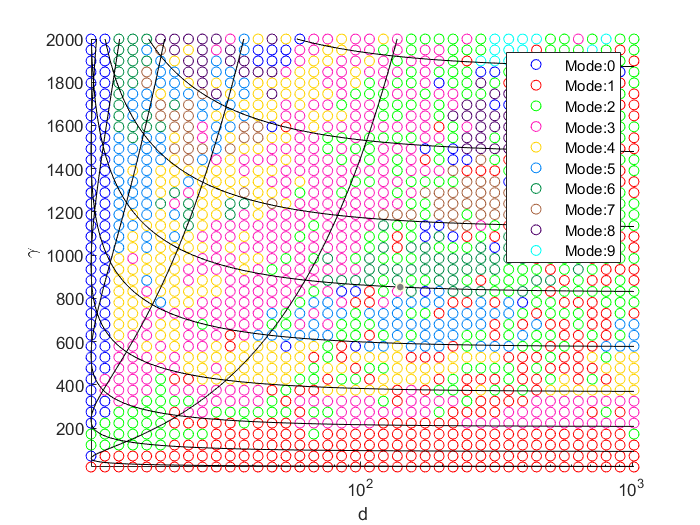

loglog_mode(Schnack3_room,'show_raster',1)

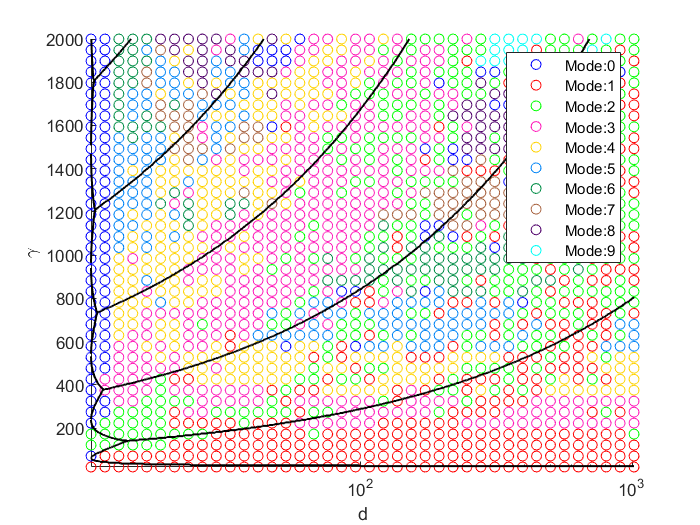

loglog_mode(Schnack3_room,'show_raster',2)

Schnack3_mroom = Schnack_median_room_mode(Schnack3_mroom,'Maximal_mode',true,'max_mode',true);

Index exceeds the number of array elements (1).

Error in Schnack_median_room/Schnack_median_room_mode (line 42)
        mode_variance(i_g,i_d) = temp_variance(temp_mode(i_g,i_d));

loglog_mode(Schnack3_mroom,'show_raster',0)

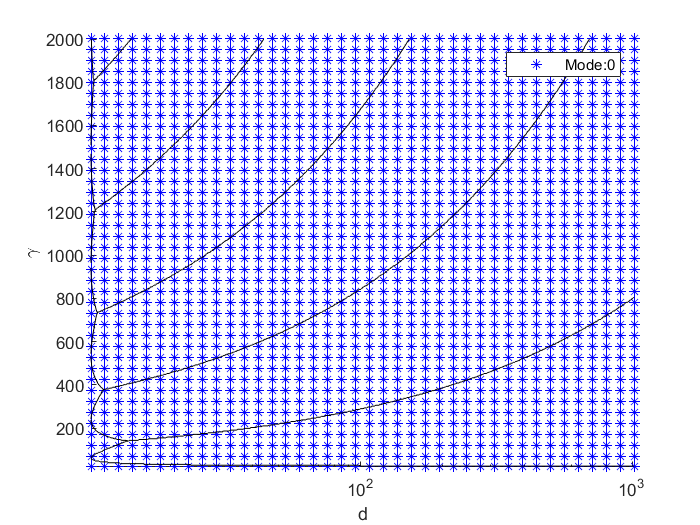

Schnack3_mroom = Schnack_median_room_mode(Schnack3_mroom,'max_mode',true);
loglog_mode2(Schnack3_mroom,'show_raster',2)

Schnack3_mroom.mode_variance(Schnack3_mroom.mode_variance > 4) = 4;

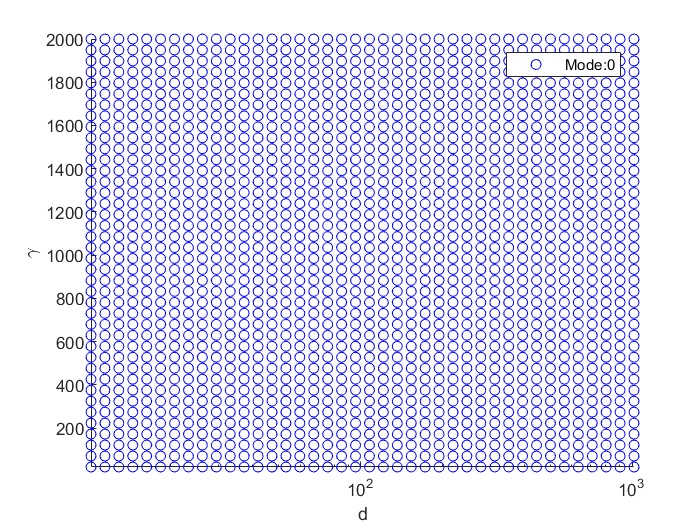

loglog_median_mode(Schnack3_mroom)

% Schnack3 = Sol_Schnack_max_mode2(Schnack3,j_prom);
% loglog_mode3(Schnack2,'show_raster',0)
% loglog_mode2(Schnack2,'show_raster',0)
% Schnack1 = Sol_Schnack_max_mode2(Schnack1,j_prom);
% loglog_mode2(Schnack1,'show_raster',0)